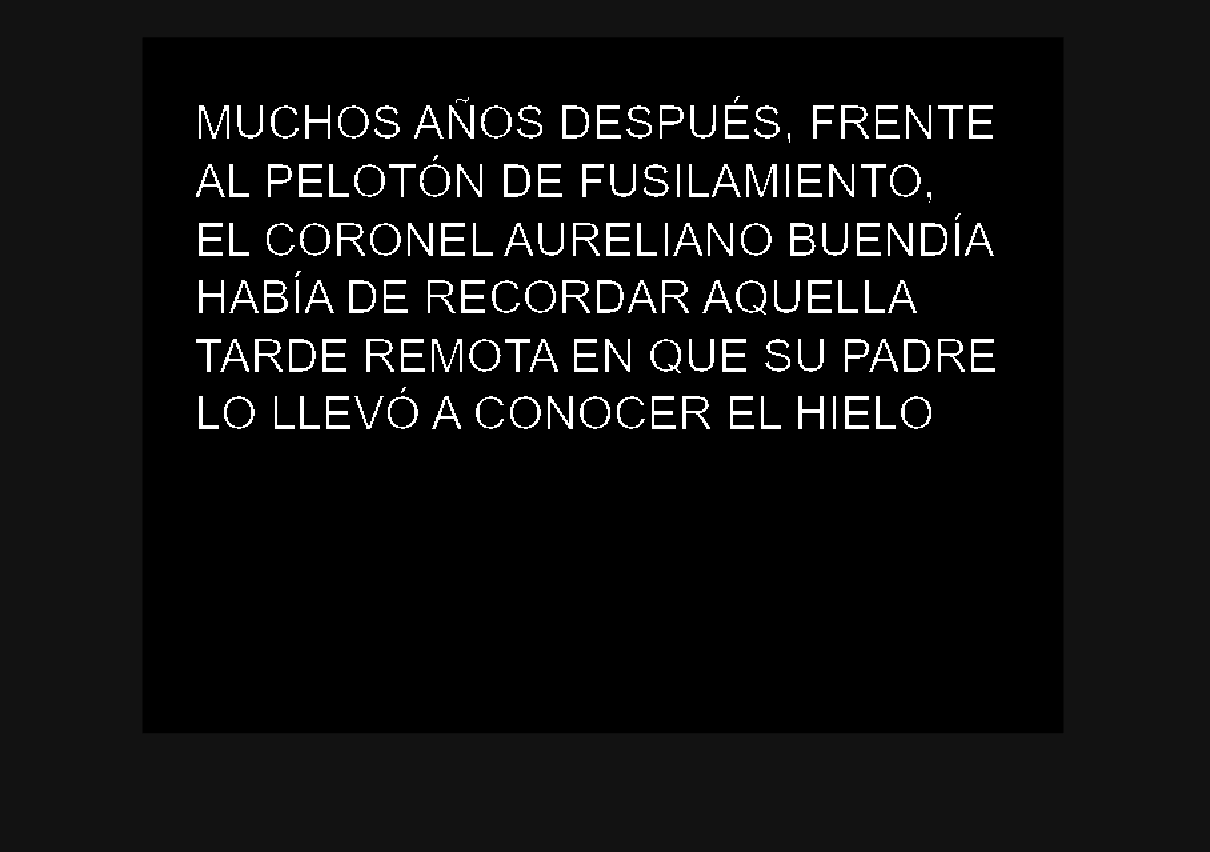

%%1. Binarization
task1Binarization('origen.png', 0.01);

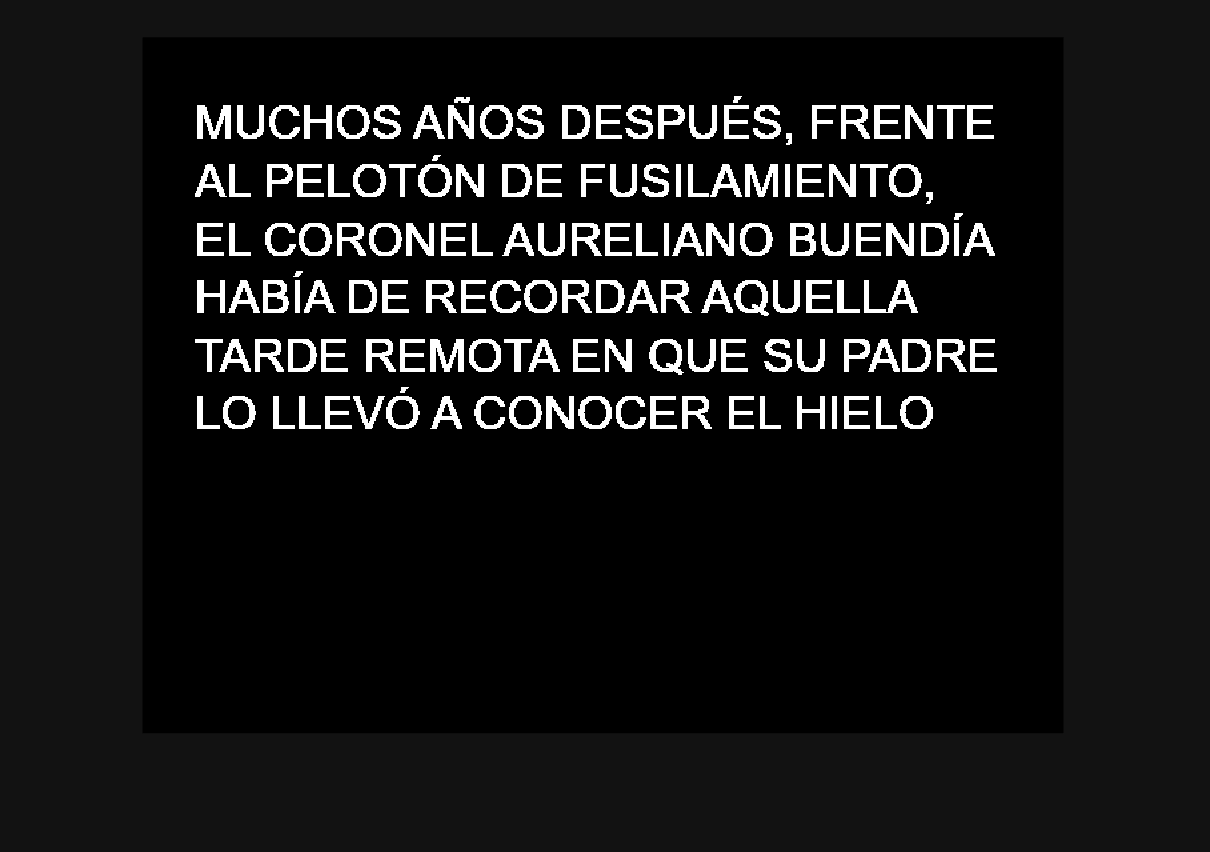

task1Binarization('origen.png', 0.99);

Lower threshold = líneas más finas, capta menos. A mayor theshold, mayor densidad de píxeles que ha captado. Otsu finds the optimal  threshold.

imBinarized = task1BinarizationAdvanced('origen.png');

Otsu threshold: 0.506


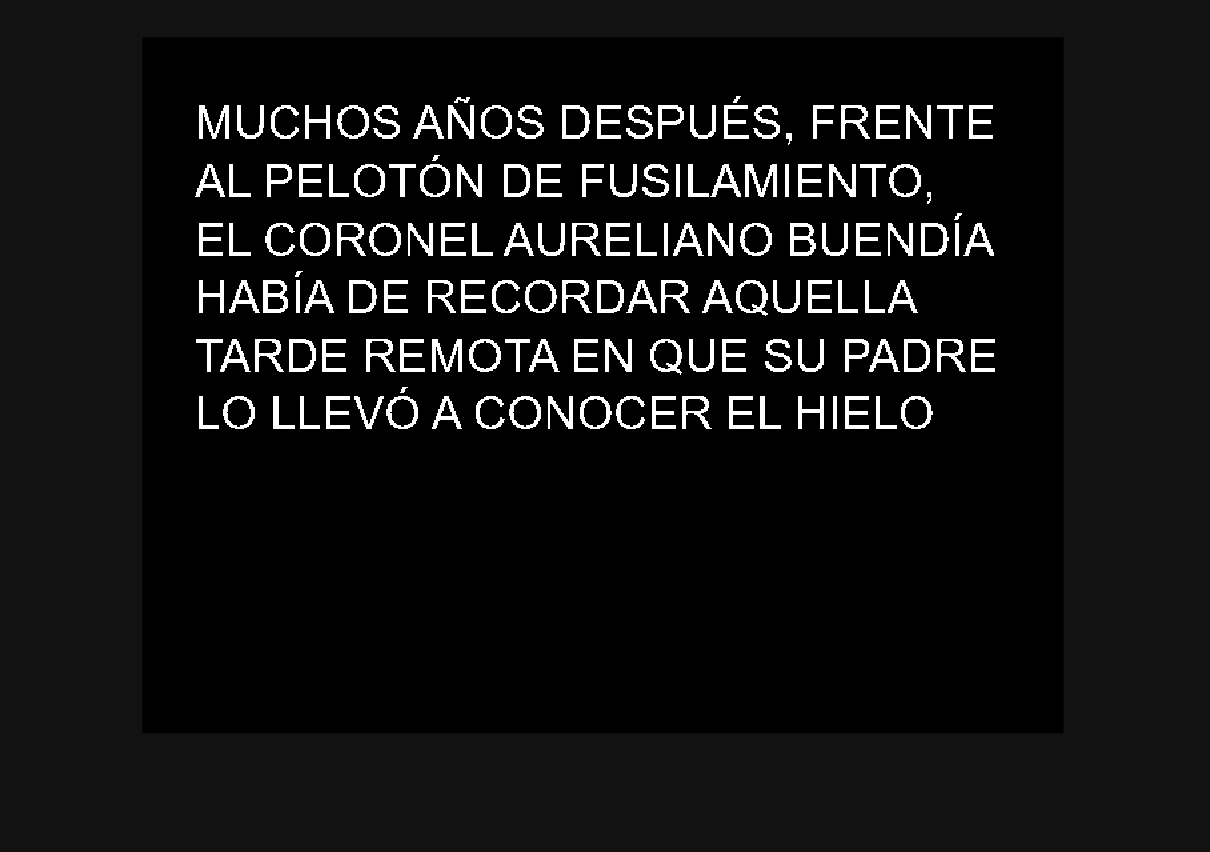

imshow(imBinarized); %solo para testeo, LUEGO QUITAR

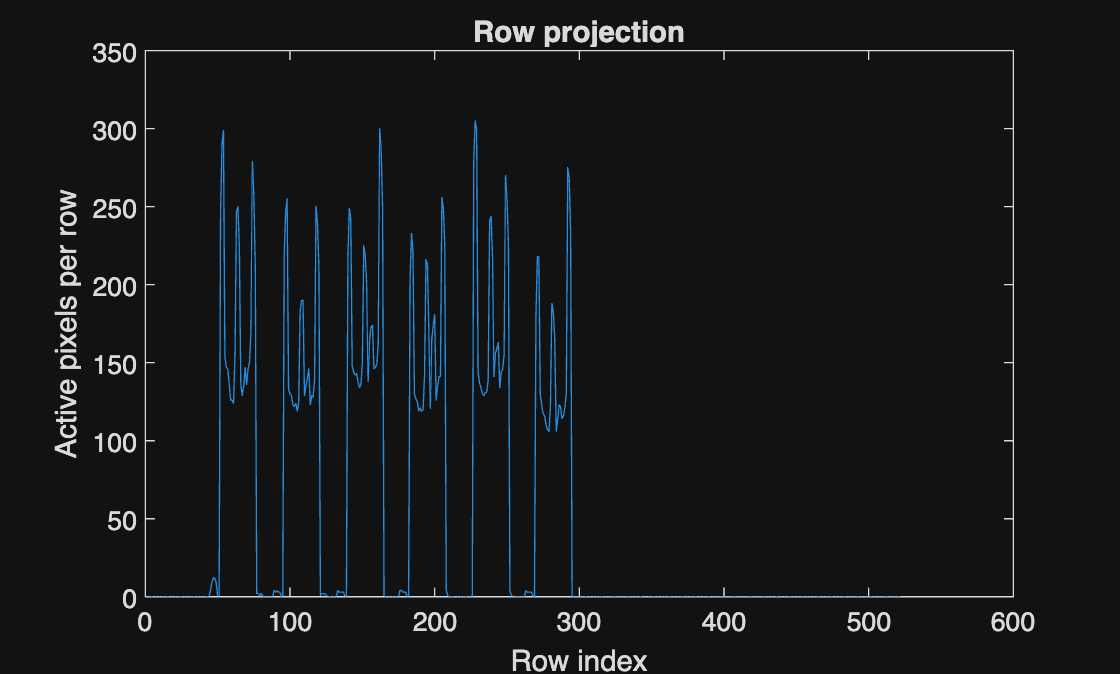

%%2. Segmenting Rows
% Method: vertical projection
% Sum image rows to detect text lines
rowProjection = task2RowProjection(imBinarized); 

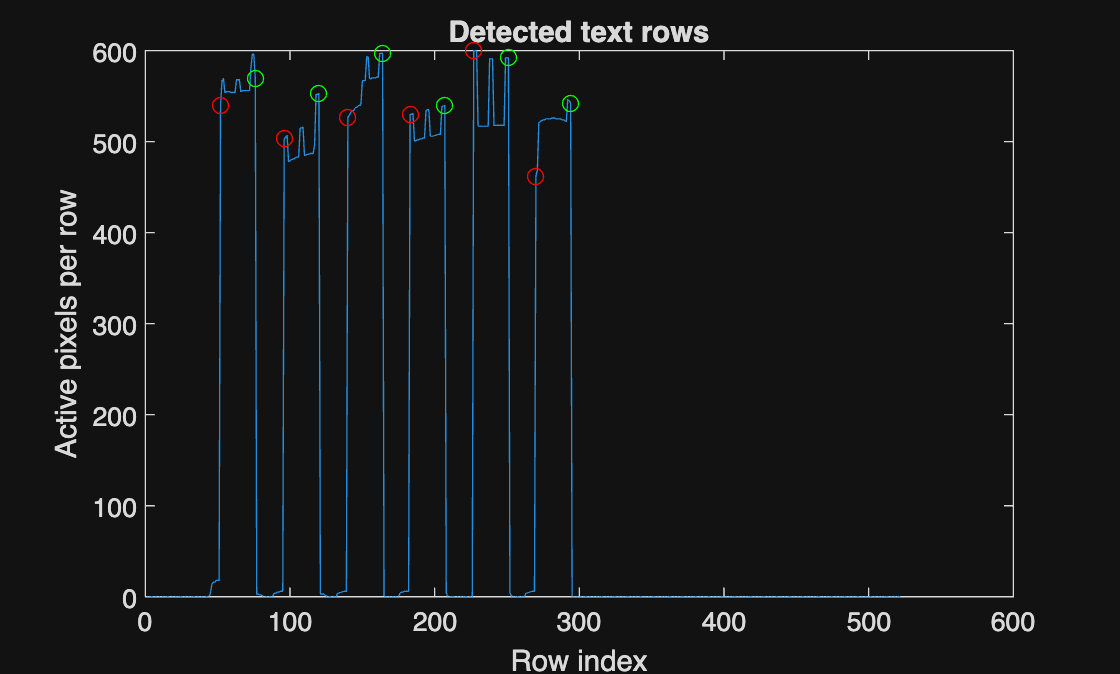


[rowStarts, rowEnds, rowMask] = task2SegmentRows(imBinarized);

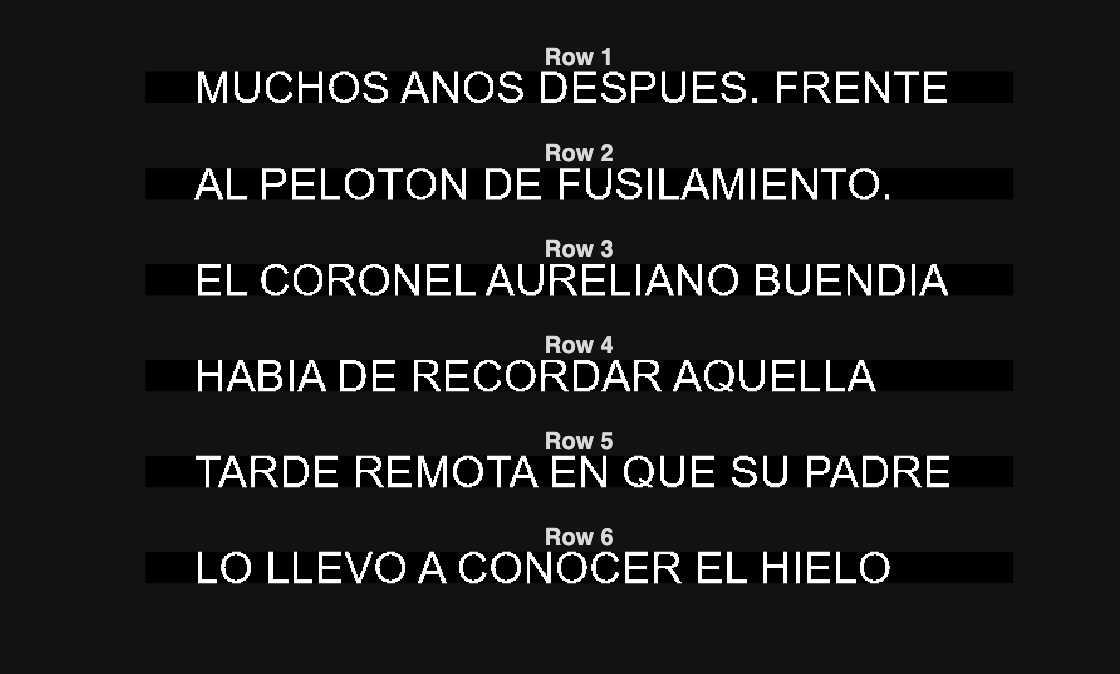


rowImages = task2ExtractRows(imBinarized, rowStarts, rowEnds);